clear all
allResults = sensiAna_YJM(0.1,1);

allResults.maxT

ans = struct with fields:
      prop_R0: [2.1817 2.2792 2.3347]
    homophily: [2.2325 2.2792 2.3296]
     alpha_P0: [2.2659 2.2792 2.2927]
     alpha_P1: [2.2593 2.2792 2.2989]
     alpha_R0: [2.2787 2.2792 2.2798]
      omega_R: [2.1490 2.2792 2.4505]
      omega_P: [2.3794 2.2792 2.1994]
          k_R: [2.2969 2.2792 2.2643]
          k_P: [2.2751 2.2792 2.2843]
          c_R: [2.3629 2.2792 2.2126]
          c_P: [2.2470 2.2792 2.3210]
        kappa: [2.5452 2.2792 1.9947]
        delta: [2.3224 2.2792 2.2377]
           s_: [2.2603 2.2792 2.2912]
        C_at0: [2.2728 2.2792 2.2855]
        C_oc0: [2.2803 2.2792 2.2783]
       C_veg0: [2.2671 2.2792 2.2949]
        C_so0: [2.2886 2.2792 2.2714]
          k_p: [2.2553 2.2792 2.3445]
          k_c: [2.2818 2.2792 2.2767]
          k_M: [2.3140 2.2792 2.2533]
          k_r: [2.3474 2.2792 2.2582]
          E_a: [2.2548 2.2792 2.3341]
         k_sr: [2.3605 2.2792 2.2811]
          k_t: [2.2795 2.2792 2.2960]
            c: [2.2644 2

res_ = allResults;
resNames = fieldnames(allResults.maxT);

give2barh = [];
fldnames  = fieldnames(res_.maxT);
for i =1:length(fldnames  )
    fldname_ = fldnames{i};
    give2barh = [give2barh; res_.maxT.(fldname_)];
end

ctst = categorical(fldnames)'

ctst = 1×37 categorical array
     prop_R0      homophily      alpha_P0      alpha_P1      alpha_R0      omega_R      omega_P      k_R      k_P      c_R      c_P      kappa      delta      s_      C_at0      C_oc0      C_veg0      C_so0      k_p      k_c      k_M      k_r      E_a      k_sr      k_t      c      A      S      tao_CH4      P_0      F_0      chi      zeta      f_max      omega      T_c      t_f 


% sort A in descending order (decreasing A values) 
% and keep the sort index in "sortIdx"
%[A,sortIdx] = sort(std(give2barh'),'descend');
%sizeBar = abs((give2barh(:,1))' - (give2barh(:,2))') + abs((give2barh(:,2))' - (give2barh(:,3))');
max_temp = max(give2barh, [],2);
min_temp = min(give2barh, [],2);
sizeBar = abs((max_temp)' - (give2barh(:,2))' + (give2barh(:,2))' - (min_temp)');
[A,sortIdx] = sort(sizeBar,'ascend');

% sort B using the sorting index
B = give2barh(sortIdx,:);
sortedNames = categorical(resNames(sortIdx))';
%sortedNames = reordercats(sortedNamesNice, fliplr(namesNice));
mn1 = mean(give2barh);
mn1 = mn1(2); 

resNames

resNames = 37×1 cell array
    {'prop_R0'  }
    {'homophily'}
    {'alpha_P0' }
    {'alpha_P1' }
    {'alpha_R0' }
    {'omega_R'  }
    {'omega_P'  }
    {'k_R'      }
    {'k_P'      }
    {'c_R'      }
    {'c_P'      }
    {'kappa'    }
    {'delta'    }
    {'s_'       }
    {'C_at0'    }
    {'C_oc0'    }
    {'C_veg0'   }
    {'C_so0'    }
    {'k_p'      }
    {'k_c'      }
    {'k_M'      }
    {'k_r'      }
    {'E_a'      }
    {'k_sr'     }
    {'k_t'      }
    {'c'        }
    {'A'        }
    {'S'        }
    {'tao_CH4'  }
    {'P_0'      }
    {'F_0'      }
    {'chi'      }
    {'zeta'     }
    {'f_max'    }
    {'omega'    }
    {'T_c'      }
    {'t_f'      }


resNames(11)

ans = 1×1 cell array
    {'c_P'}


temp_str = resNames(1); % cell
if strcmp(temp_str{1}, 'homophily')
    resNames(2) = {'\alpha_{P0}'};
    resNames(3) = {'\alpha_{P1}'};
    resNames(4) = {'\alpha_{R0}'};
    resNames(5) = {'\omega_R'};
    resNames(6) = {'\omega_P'};
    
    temp_str2 = resNames(11);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 1;
        resNames(11) ={'\kappa'};
    else
        incr = 0;
    end
    
    resNames(11+incr) = {'\delta'};
    resNames(15+incr) = {'C_{at0}'};
    resNames(16+incr) = {'C_{oc0}'};
    resNames(17+incr) = {'C_{veg0}'};
    resNames(18+incr) = {'C_{so0}'};
    resNames(24+incr) = {'k_{sr}'};
    resNames(29+incr) = {'\tau_{CH4}'};
    resNames(33+incr) = {'\chi'};
    resNames(34+incr) = {'\zeta'};
    resNames(35+incr) = {'f_{max}'};
    resNames(36+incr) = {'\omega'};
end
if strcmp(temp_str{1}, 'prop_R0')
    resNames(1) = {'prop_{R0}'};
    resNames(3) = {'\alpha_{P0}'};
    resNames(4) = {'\alpha_{P1}'};
    resNames(5) = {'\alpha_{R0}'};
    resNames(6) = {'\omega_R'};
    resNames(7) = {'\omega_P'};
    
    temp_str2 = resNames(12);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 1;
        resNames(12) ={'\kappa'};
    else
        incr = 0;
    end    
    
    resNames(12+incr) = {'\delta'};
    resNames(14+incr) = {'C_{at0}'};
    resNames(15+incr) = {'C_{oc0}'};
    resNames(16+incr) = {'C_{veg0}'};
    resNames(17+incr) = {'C_{so0}'};
    resNames(23+incr) = {'k_{sr}'};
    resNames(28+incr) = {'\tau_{CH4}'};
    resNames(31+incr) = {'\chi'};
    resNames(32+incr) = {'\zeta'};
    resNames(33+incr) = {'f_{max}'};
    resNames(34+incr) = {'\omega'};
end

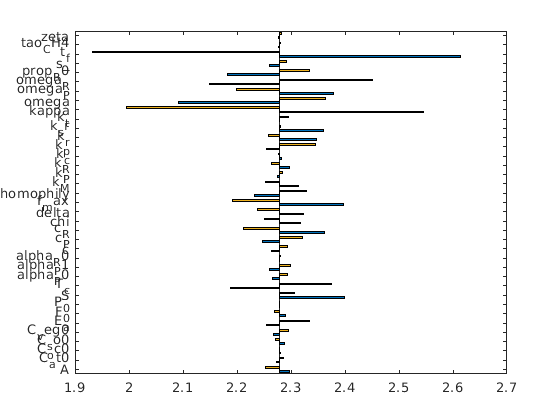

barh(ctst, give2barh, 'BaseValue', mn1)

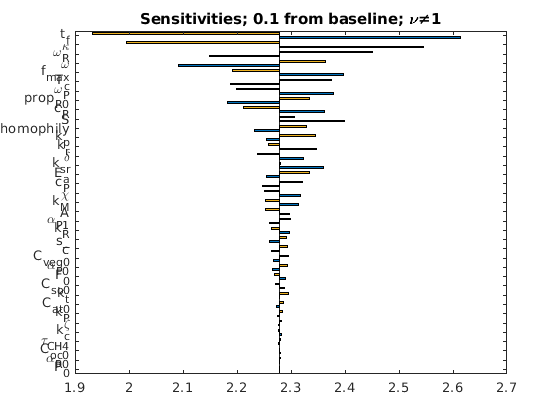

clf
barh(give2barh(sortIdx,:), 'BaseValue', mn1)
len__ = length(sortIdx);
yticks(1:len__)
set(gca, "YTickLabel", resNames(sortIdx))
title('Sensitivities; 0.1 from baseline; \nu\neq1')

% Instead of varying prop_R0 and fixing x0=0.05, vary x0 and fix prop_R0 = 0.25

clear all
allResults = sensiAna_YJM(0.1,0);

allResults.maxT

ans = struct with fields:
    homophily: [2.2325 2.2792 2.3296]
     alpha_P0: [2.2659 2.2792 2.2927]
     alpha_P1: [2.2593 2.2792 2.2989]
     alpha_R0: [2.2787 2.2792 2.2798]
      omega_R: [2.1490 2.2792 2.4505]
      omega_P: [2.3794 2.2792 2.1994]
          k_R: [2.2969 2.2792 2.2643]
          k_P: [2.2751 2.2792 2.2843]
          c_R: [2.3629 2.2792 2.2126]
          c_P: [2.2470 2.2792 2.3210]
        kappa: [2.5452 2.2792 1.9947]
        delta: [2.3224 2.2792 2.2377]
           s_: [2.2603 2.2792 2.2912]
          x0_: [2.4236 2.2792 2.1976]
        C_at0: [2.2728 2.2792 2.2855]
        C_oc0: [2.2803 2.2792 2.2783]
       C_veg0: [2.2671 2.2792 2.2949]
        C_so0: [2.2886 2.2792 2.2714]
          k_p: [2.2553 2.2792 2.3445]
          k_c: [2.2818 2.2792 2.2767]
          k_M: [2.3140 2.2792 2.2533]
          k_r: [2.3474 2.2792 2.2582]
          E_a: [2.2548 2.2792 2.3341]
         k_sr: [2.3605 2.2792 2.2811]
          k_t: [2.2795 2.2792 2.2960]
            c: [2.2644 2

res_ = allResults;
resNames = fieldnames(allResults.maxT);

give2barh = [];
fldnames  = fieldnames(res_.maxT);
for i =1:length(fldnames  )
    fldname_ = fldnames{i};
    give2barh = [give2barh; res_.maxT.(fldname_)];
end

ctst = categorical(fldnames)'

ctst = 1×37 categorical array
     homophily      alpha_P0      alpha_P1      alpha_R0      omega_R      omega_P      k_R      k_P      c_R      c_P      kappa      delta      s_      x0_      C_at0      C_oc0      C_veg0      C_so0      k_p      k_c      k_M      k_r      E_a      k_sr      k_t      c      A      S      tao_CH4      P_0      F_0      chi      zeta      f_max      omega      T_c      t_f 


% sort A in descending order (decreasing A values) 
% and keep the sort index in "sortIdx"
%[A,sortIdx] = sort(std(give2barh'),'descend');
%sizeBar = abs((give2barh(:,1))' - (give2barh(:,2))') + abs((give2barh(:,2))' - (give2barh(:,3))');
max_temp = max(give2barh, [],2);
min_temp = min(give2barh, [],2);
sizeBar = abs((max_temp)' - (give2barh(:,2))' + (give2barh(:,2))' - (min_temp)');
[A,sortIdx] = sort(sizeBar,'ascend');

% sort B using the sorting index
B = give2barh(sortIdx,:);
sortedNames = categorical(resNames(sortIdx))';
%sortedNames = reordercats(sortedNamesNice, fliplr(namesNice));
mn1 = mean(give2barh);
mn1 = mn1(2); 

resNames

resNames = 37×1 cell array
    {'homophily'}
    {'alpha_P0' }
    {'alpha_P1' }
    {'alpha_R0' }
    {'omega_R'  }
    {'omega_P'  }
    {'k_R'      }
    {'k_P'      }
    {'c_R'      }
    {'c_P'      }
    {'kappa'    }
    {'delta'    }
    {'s_'       }
    {'x0_'      }
    {'C_at0'    }
    {'C_oc0'    }
    {'C_veg0'   }
    {'C_so0'    }
    {'k_p'      }
    {'k_c'      }
    {'k_M'      }
    {'k_r'      }
    {'E_a'      }
    {'k_sr'     }
    {'k_t'      }
    {'c'        }
    {'A'        }
    {'S'        }
    {'tao_CH4'  }
    {'P_0'      }
    {'F_0'      }
    {'chi'      }
    {'zeta'     }
    {'f_max'    }
    {'omega'    }
    {'T_c'      }
    {'t_f'      }


resNames(33)

ans = 1×1 cell array
    {'zeta'}


temp_str = resNames(1); % cell
if strcmp(temp_str{1}, 'homophily')
    resNames(2) = {'\alpha_{P0}'};
    resNames(3) = {'\alpha_{P1}'};
    resNames(4) = {'\alpha_{R0}'};
    resNames(5) = {'\omega_R'};
    resNames(6) = {'\omega_P'};
    
    temp_str2 = resNames(11);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 0;
        resNames(11) ={'\kappa'};
    else
        incr = 0;
    end
    
    resNames(11+incr) = {'\delta'};
    resNames(15+incr) = {'C_{at0}'};
    resNames(16+incr) = {'C_{oc0}'};
    resNames(17+incr) = {'C_{veg0}'};
    resNames(18+incr) = {'C_{so0}'};
    resNames(24+incr) = {'k_{sr}'};
    resNames(29+incr) = {'\tau_{CH4}'};
    resNames(32+incr) = {'\chi'};
    resNames(33+incr) = {'\zeta'};
    resNames(34+incr) = {'f_{max}'};
    resNames(35+incr) = {'\omega'};
end
if strcmp(temp_str{1}, 'prop_R0')
    resNames(1) = {'prop_{R0}'};
    resNames(3) = {'\alpha_{P0}'};
    resNames(4) = {'\alpha_{P1}'};
    resNames(5) = {'\alpha_{R0}'};
    resNames(6) = {'\omega_R'};
    resNames(7) = {'\omega_P'};
    
    temp_str2 = resNames(12);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 1;
        resNames(12) ={'\kappa'};
    else
        incr = 0;
    end    
    
    resNames(12+incr) = {'\delta'};
    resNames(14+incr) = {'C_{at0}'};
    resNames(15+incr) = {'C_{oc0}'};
    resNames(16+incr) = {'C_{veg0}'};
    resNames(17+incr) = {'C_{so0}'};
    resNames(23+incr) = {'k_{sr}'};
    resNames(28+incr) = {'\tau_{CH4}'};
    resNames(31+incr) = {'\chi'};
    resNames(32+incr) = {'\zeta'};
    resNames(33+incr) = {'f_{max}'};
    resNames(34+incr) = {'\omega'};
end

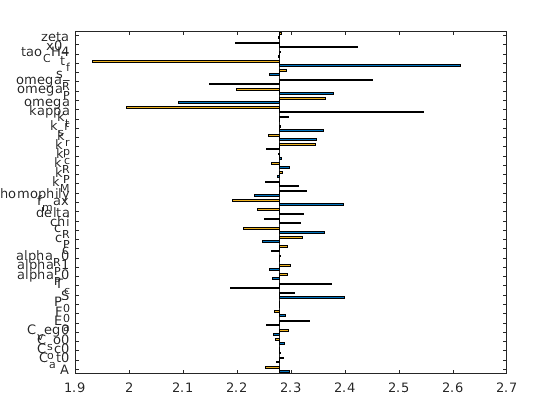

barh(ctst, give2barh, 'BaseValue', mn1)

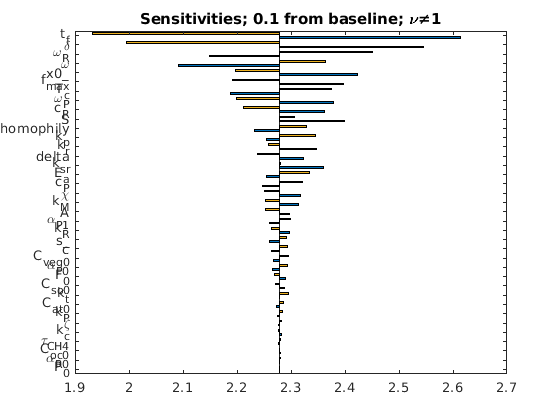

clf
barh(give2barh(sortIdx,:), 'BaseValue', mn1)
len__ = length(sortIdx);
yticks(1:len__)
set(gca, "YTickLabel", resNames(sortIdx))
title('Sensitivities; 0.1 from baseline; \nu\neq1')

if ~(1==0)
    disp('hello')
end

hello
